# Notebook 1.5: Calculating SNR after Kernel Transformation

This notebook is going to be a section on the SNR of signals after we transform them into the new feature space projection. This is to determine if the Kernel transformations are actually sufficient at changing the SNR of a signal. 

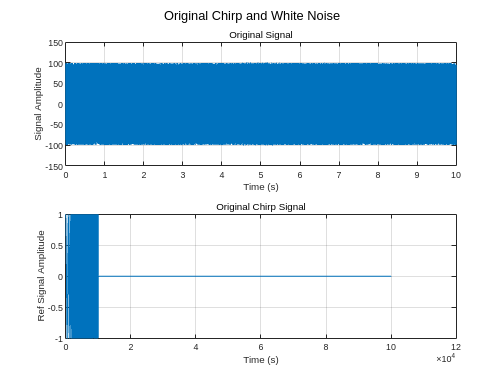

% --Create Signals
    alpha = 10;
    beta = 10;
    [white_signal, brown_signal, reference, ref_chirp_long, time] = generate_signals(alpha, beta);

% --Plotting out signals
    figure()
    subplot(2,1,1)
    plot(time,white_signal)
        hold on
        grid on
        xlabel("Time (s)")
        ylabel("Signal Amplitude")
        subtitle("Original Signal")

    subplot(2,1,2)
    plot(ref_chirp_long)
        hold on
        grid on
        xlabel("Time (s)")
        subtitle("Original Chirp Signal")
        sgtitle("Original Chirp and White Noise")
        ylabel("Ref Signal Amplitude")

% --Calculating SNR for signal
    noise = white_signal - ref_chirp_long;
    noise_power = sum(noise.^2)/(2*length(noise) + 1);
    signal_power = sum(reference.^2)/(2*length(reference) + 1);
    SNR = 10*log10(signal_power/noise_power)

SNR = -38.2225

Because we are doing a kernel transformation of our signal, we now need to determine the signal via a different method. We can't just take the signal reference and then transform it. Instead what we need to do is take the kernel of the noise and then subtract it from the kernel transformation of the entire data set. This yields the cubic kernel of the signal component.

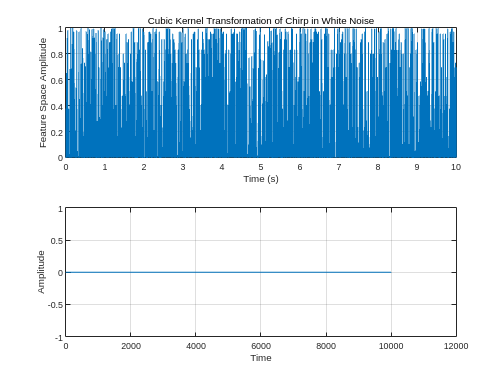

% --Transforming Kernel Functions
    k_data = rbf_kernel(white_signal);
    k_noise = rbf_kernel(noise);
    k_signal = k_data - k_noise;
    k_signal = k_signal(45000:55000);

% --Plotting new versions of the signals
    figure()
    subplot(2,1,1)
    plot(time, k_noise)
        hold on
        grid on
        xlabel("Time (s)")
        ylabel("Feature Space Amplitude")
        subtitle("Cubic Kernel Transformation of Chirp in White Noise")
        
    subplot(2,1,2)
    plot(k_signal)
        hold on
        grid on
        xlabel("Time")
        ylabel("Amplitude")

This is the entire signal that is decomposed into the two parts, cubic kernel transformation of the signal and the cubic kernel transformation of the noise itself. Now I want to see the SNR of the cubic signals.

% --Calculating SNR
    signal_power = sum(k_signal.^2)/(2*length(k_signal) + 1);
    noise_power = sum(k_noise.^2)/(2*length(k_noise) + 1);
    SNR = 10*log10(signal_power/noise_power)

SNR = -Inf

## For Loop To Loop Through SNR Values

Cubic Kernel Simulation

% --Setup
    alphas = 60:-1:1;
    cubic_SNRs = [];
    cubic_new_SNRs = [];

% --For loops
    for i = 1:length(alphas)

        for j = 1:10
        
            % --Getting SNRs
                alpha = alphas(i);
                [white_signal, brown_signal, reference, ref_chirp_long, time] = generate_signals(alpha, beta);
                noise = white_signal - ref_chirp_long;
                signal = white_signal - noise;
                signal = signal(45000:55000);
                
                noise_power = sum(noise.^2)/(2*length(noise) + 1);
                signal_power = sum(signal.^2)/(2*length(signal) + 1);
                SNR = 10*log10(signal_power/noise_power);
                cubic_SNRs = [cubic_SNRs, SNR];
    
            % --Transforming Kernel Functions
                k_data = cubic_kernel(white_signal);
                k_noise = cubic_kernel(noise);
                k_signal = k_data - k_noise;
                k_signal = k_signal(45000:55000);
                
            % --Calculating SNR
                signal_power = sum(k_signal.^2)/(2*length(k_signal) + 1);
                noise_power = sum(k_noise.^2)/(2*length(k_noise) + 1);
                SNR = 10*log10(signal_power/noise_power);
                cubic_new_SNRs = [cubic_new_SNRs, SNR];

        end

    end

L-Abs Kernel Simulation

% --Setup
    LAbs_SNRs = [];
    LAbs_new_SNRs = [];

% --For loops
    for i = 1:length(alphas)

        for j = 1:10
        
            % --Getting SNRs
                alpha = alphas(i);
                [white_signal, brown_signal, reference, ref_chirp_long, time] = generate_signals(alpha, beta);
                noise = white_signal - ref_chirp_long;
                signal = white_signal - noise;
                signal = signal(45000:55000);
                
                noise_power = sum(noise.^2)/(2*length(noise) + 1);
                signal_power = sum(signal.^2)/(2*length(signal) + 1);
                SNR = 10*log10(signal_power/noise_power);
                LAbs_SNRs = [LAbs_SNRs, SNR];
    
            % --Transforming Kernel Functions
                k_data = Labs_kernel(white_signal, white_signal);
                k_noise = Labs_kernel(noise, noise);
                k_signal = k_data - k_noise;
                k_signal = k_signal(45000:55000);
                
            % --Calculating SNR
                signal_power = sum(k_signal.^2)/(2*length(k_signal) + 1);
                noise_power = sum(k_noise.^2)/(2*length(k_noise) + 1);
                SNR = 10*log10(signal_power/noise_power);
                LAbs_new_SNRs = [LAbs_new_SNRs, SNR];

        end

    end

RBF - Kernel Simulation

% --Setup
    RBF_SNRs = [];
    RBF_new_SNRs = [];

% --For loops
    for i = 1:length(alphas)

        for j = 1:10
        
            % --Getting SNRs
                alpha = alphas(i);
                [white_signal, brown_signal, reference, ref_chirp_long, time] = generate_signals(alpha, beta);
                noise = white_signal - ref_chirp_long;
                signal = white_signal - noise;
                signal = signal(45000:55000);
                
                noise_power = sum(noise.^2)/(2*length(noise) + 1);
                signal_power = sum(signal.^2)/(2*length(signal) + 1);
                SNR = 10*log10(signal_power/noise_power);
                RBF_SNRs = [RBF_SNRs, SNR];
    
            % --Transforming Kernel Functions
                k_data = rbf_kernel(white_signal);
                k_noise = rbf_kernel(noise);
                k_signal = k_data - k_noise;
                k_signal = k_signal(45000:55000);
                
            % --Calculating SNR
                signal_power = sum(k_signal.^2)/(2*length(k_signal) + 1);
                noise_power = sum(k_noise.^2)/(2*length(k_noise) + 1);
                SNR = 10*log10(signal_power/noise_power);
                RBF_new_SNRs = [RBF_new_SNRs, SNR];

        end

    end

## Plotting The Results to Simulations

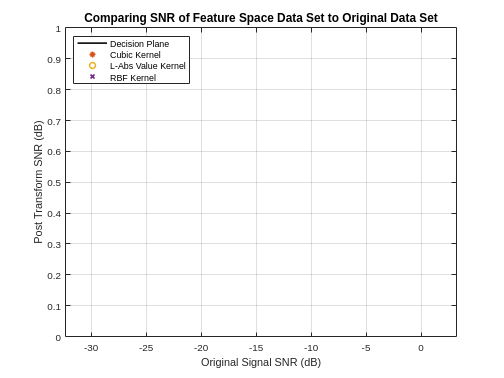

% --Plotting
    figure()
    plot(cubic_SNRs, cubic_SNRs, 'Color', [0.1 0.1 0.1], 'LineWidth', 2)
        hold on
        grid on
        xlim([-32.3 3.2])
        xlabel("Original Signal SNR (dB)")
        ylabel("Post Transform SNR (dB)")
        title("Comparing SNR of Feature Space Data Set to Original Data Set","FontSize",12)
    plot(cubic_SNRs, cubic_new_SNRs, '*', 'LineWidth', 1.5)
    plot(LAbs_SNRs, LAbs_new_SNRs, 'o','LineWidth', 1.5)
    plot(RBF_SNRs, RBF_new_SNRs, 'x', 'LineWidth', 2)
        legend('Decision Plane', 'Cubic Kernel', 'L-Abs Value Kernel', 'RBF Kernel', "Location", "northwest")

function kf = cubic_kernel(x)

    % --Find kernel
        kf = (x + 1).^3;

end

function kf = Labs_kernel(x, y)

    % --Find the kernel
        kf = abs(x + y);

end

function kf = rbf_kernel(x)
        
    % --Parameters
        sigma = 0.3;

    % --Find kernel
        kf = exp(-1.*(x.^2) ./ (2*sigma));

end